%%%% Step1 : Reading the audio File 
[x, Fs] =audioread('listen-to-the-ancient-egyptions-tv.wav');

filter_coefficients = load('filters.txt');

% Determine the number of filters and coefficients per filter
% This is just a placeholder, the actual number should be set according to the standard or the structure of the file
num_filters = 32; % for example, if there are 32 filters
coeffs_per_filter = (length(filter_coefficients)-1) / num_filters;
total_coeffs = coeffs_per_filter * num_filters;

% Reshape the coefficients into a matrix where each row corresponds to one filter's coefficients
h = reshape(filter_coefficients(1:total_coeffs), coeffs_per_filter, num_filters)';

% Initialize the impulse response matrix H
H = zeros(size(h));

% Calculate the impulse response for each filter
for i = 1:num_filters % For each filter
    for n = 1:coeffs_per_filter % For each sample
        % The index i-1 is used for 0-based indexing used in the given equation
        H(i, n) = h(i, n) * cos((i+1/2)*(n-16)*pi/32);
    end
end

z=zeros(length(x),num_filters);
for i=1:num_filters
    y = myConvo(x,H(i,:));
    z(:,i)=y;
end
% Define the downsampling factor (N)
downsamplingFactor = 32;

% Initialize a cell array to store the downsampled and concatenated signals
downsampledConcatenatedSignals = cell(1, size(z, 2));

% Iterate through each column of the signal matrix (each channel)
for channel = 1:size(z, 2)
    % Extract the current channel's signal
    currentChannelSignal = z(:, channel);
    
    % Downsample the signal by a factor of 32
    downsampledSignal = downsample(currentChannelSignal, downsamplingFactor);
    
    % Store the downsampled signal in the cell array
    downsampledConcatenatedSignals{channel} = downsampledSignal;
end
% Concatenate the downsampled signals into a single 2D matrix
downsampledConcatenatedMatrix = horzcat(downsampledConcatenatedSignals{:});


**Psychoacoustic One**

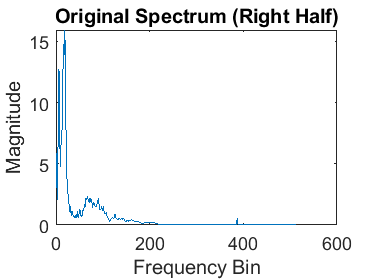

[x, Fs] =audioread('listen-to-the-ancient-egyptions-tv.wav');
load('Signal_Spectrum (1).mat');
N=1024;
X_right_half = Signal_Spectrum(N/2+1:end); %highwe frequency content

figure;
plot(abs(X_right_half));
title('Original Spectrum (Right Half)');
xlabel('Frequency Bin');
ylabel('Magnitude');

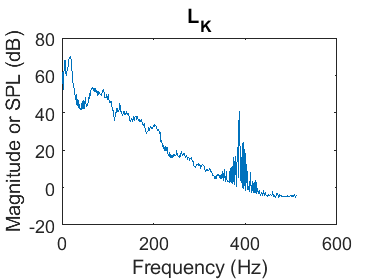

L_K = zeros(1, N/2);
A = zeros(1, N/2);

for k = 1:N/2
    L_K(k) = 96 +10*log10((4/N.^2)*abs(X_right_half(k)).^2*8/3);
end

figure;
plot(L_K);
xlabel('Frequency (Hz)');
ylabel('Magnitude or SPL (dB)');
title('L_K');

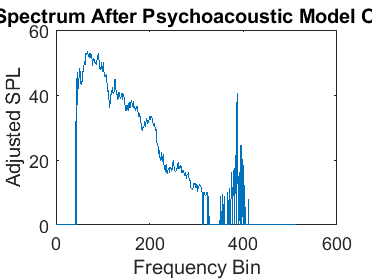

adjustedSPL =zeros(size(L_K));
for i=1:(N/2)
    A(i)=((3.64*(i/1000).^(-0.8))-(6.5*exp(-0.6*((i/1000)-3.3).^2))+(10.^-3*(i/1000).^4));
    if L_K(i)<=A(i)
        adjustedSPL(i)=0;
    else
        adjustedSPL(i)=L_K(i);
    end
end
figure;
plot(adjustedSPL);
title('Spectrum After Psychoacoustic Model One');
xlabel('Frequency Bin');
ylabel('Adjusted SPL');

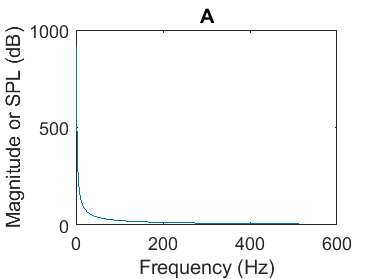

figure;
plot(A);
xlabel('Frequency (Hz)');
ylabel('Magnitude or SPL (dB)');
title('A');

**Psychoacoustic Two**

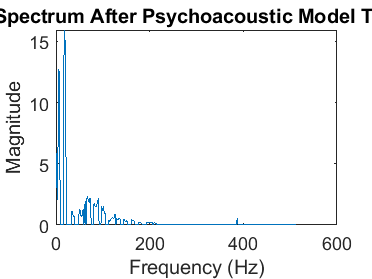

% Divide spectrum into 32 sub-bands
numSubBands = 32;

% Initialize an array to hold the sub-band spectra
subbands = zeros(numSubBands, (N/2)/numSubBands);

for i = 1:numSubBands
    % Calculate the indices for the current sub-band
    startIndex = (i - 1) * ((N/2) /numSubBands) + 1;
    endIndex = i * ((N/2) /numSubBands);

    % Extract the portion of the magnitude spectrum for this sub-band
    subbands(i, :) = X_right_half(startIndex:endIndex);
end

% Define delta value
delta = 1.5;

% Initialize the combined spectrum
combinedSpectrumAfterModelTwo = zeros(1, N/2);


% Loop over each sub-band
for i = 1:numSubBands
    % Extract the current sub-band
    currentSubBand = subbands(i, :);

    % Find global maximum
    [globalMax, globalMaxIndex] = max(currentSubBand);

    % Find local maxima
    [localMaxValues, localMaxIndices] = findpeaks(currentSubBand);

    % Combine global and local maxima
    maxValues = [globalMax, localMaxValues];
    maxIndices = [globalMaxIndex, localMaxIndices];

    % Loop over each masker
    for j = 1:length(maxValues)
        maskerSPL = maxValues(j);
        maskerFreq = maxIndices(j); % You may need to convert this index to actual frequency
    
        % Apply masking only if SPL is greater than 0 dB
        if maskerSPL > 0
            % Calculate masked range using your masking_threshold function
            maskedRange = masking_threshold(maskerSPL, maskerFreq);
    
            % Ensure that maskedRange is within the valid index range of currentSubBand
            maskedRange = min(maskedRange, length(currentSubBand));
    
            % Apply masking to maskees
            for k = maskerFreq:maskedRange
                % Calculate interpolated SPL threshold
                % Assuming linear interpolation for simplicity
                interpSPL = (maskerSPL / (maskedRange - maskerFreq)) * (k - maskerFreq);
    
                % Apply delta
                interpSPL = interpSPL * delta;
    
                % Mask frequencies below the interpolated threshold
                if currentSubBand(k) < interpSPL
                    currentSubBand(k) = 0;
                end
            end
        end
    end


    % Update the combined spectrum with the current sub-band
    startIndex = (i - 1) * ((N/2) /numSubBands) + 1;
    endIndex = i * ((N/2) /numSubBands);
    combinedSpectrumAfterModelTwo(startIndex:endIndex) = currentSubBand;
end

% Plot the combined spectrum
figure;
plot(combinedSpectrumAfterModelTwo);
title('Spectrum After Psychoacoustic Model Two');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

**Encoder**

% Step 1: FFT on Each Subband
subband_fft = cell(1, 32);
for i = 1:32
    subband_fft{i} = fft(downsampledConcatenatedMatrix(i));
end

% Step 2: Multiply SPL Values with Lk Vector
% Assuming 'Lk' is already computed and available
spl_values = cellfun(@(x) abs(x), subband_fft, 'UniformOutput', false);

for i = 1:num_filters
    spl_values{i} = spl_values{i} .* combinedSpectrumAfterModelTwo;  % Adjust this as per the correct dimension of Lk
end

% Step 3: Summation and Bit Allocation
% Assuming the bit allocation logic is implemented in Bit_allocation.mxl
summed_spl_values = cellfun(@sum, spl_values);

% You can now use 'summed_spl_values' for bit allocation
BPS_signal=16;
subband_bits = zeros(1,32);
count = 0;
if BPS_signal<=16
    BPS = BPS_signal;
else
    BPS = 16;
end

b = BPS;

for i=1:1:32
    [smax,index] = max(summed_spl_values);
    index;
    
    if count < 4
        b = BPS;
    elseif count<8
        if BPS - 10 >= 2 
            b = BPS - 10;
        else
            b = 2;
        end
    elseif count<12
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<16
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<20
       if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
       end
    elseif count<24
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 2;
        end
    elseif count<28
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    else
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    end
    subband_bits(index) = b;
    count = count + 1;
    summed_spl_values(index) = -inf;
end



% Step 4: Quantization

% Total number of samples in each frame
frameSize = 384; 

% Number of samples from each sub-band in a frame
samplesPerSubband = 12; 

% Calculate the number of frames
numFrames = floor(size(downsampledConcatenatedMatrix, 1) / samplesPerSubband);

% Initialize the quantized data matrix
quantizedData = zeros(numFrames, frameSize);

% Iterate over each frame
for frameIdx = 1:numFrames
    % Initialize an empty frame
    frame = zeros(1, frameSize);
    
    % Fill the frame with data from each subband
    for subbandIdx = 1:num_filters
        % Calculate start and end indices for this subband in the frame
        startIdx = (subbandIdx - 1) * samplesPerSubband + 1;
        endIdx = startIdx + samplesPerSubband - 1;

        % Calculate indices in the downsampledConcatenatedMatrix
        dsStartIdx = (frameIdx - 1) * samplesPerSubband + 1;
        dsEndIdx = dsStartIdx + samplesPerSubband - 1;

        % Assign the samples to the frame
        frame(startIdx:endIdx) = downsampledConcatenatedMatrix(dsStartIdx:dsEndIdx, subbandIdx)';
    end
    
    % Apply quantization to the frame
    for subbandIdx = 1:num_filters
        % Quantize each subband separately
        startIdx = (subbandIdx - 1) * samplesPerSubband + 1;
        endIdx = startIdx + samplesPerSubband - 1;
        quantizedData(frameIdx, startIdx:endIdx) = Quan(frame(startIdx:endIdx), subband_bits(subbandIdx));
    end
end

**Dequantizer**

% Initialize the dequantized data matrix (same size as the quantized data)
dequantizedData = zeros(size(quantizedData));

% Number of samples from each sub-band in a frame
samplesPerSubband = 12; 

% Total number of frames
numFrames = size(quantizedData, 1);

% Number of subbands (filters)
num_filters = 32;

% Downsampling factor
downsamplingFactor = 32;

% Step 1: De-Quantization
for frameIdx = 1:numFrames
    for subbandIdx = 1:num_filters
        % Calculate start and end indices for this subband in the frame
        startIdx = (subbandIdx - 1) * samplesPerSubband + 1;
        endIdx = startIdx + samplesPerSubband - 1;

        % Retrieve the max and min values for this subband and frame
        maxi = max(quantizedData(frameIdx, startIdx:endIdx));
        mini = min(quantizedData(frameIdx, startIdx:endIdx));

        % De-quantize the subband data
        quan = quantizedData(frameIdx, startIdx:endIdx);
        dequantizedData(frameIdx, startIdx:endIdx) = DeQuan(maxi, mini, subband_bits(subbandIdx), quan);
    end
end

% Step 2: Synthesis Filter (Frequency-to-Time mapping)

% Initialize matrix for reconstructed signal
% Assuming each frame will be upsampled by a factor of 32
reconstructedSignal = zeros(numFrames * samplesPerSubband * downsamplingFactor, 1);

% Iterate over each subband
for subbandIdx = 1:num_filters
    % Initialize a temporary array to hold the reconstructed signal for the current subband
    reconstructedSubband = zeros(numFrames * samplesPerSubband * downsamplingFactor, 1);

    % Process each frame
    for frameIdx = 1:numFrames
        % Extract frame data for this subband
        startIdx = (frameIdx - 1) * samplesPerSubband + 1;
        endIdx = startIdx + samplesPerSubband - 1;
        frameData = dequantizedData(frameIdx, startIdx:endIdx);

        % Upsample the frame data
        upsampledData = upsample(frameData, downsamplingFactor);

        % Filter (reconstruct) the upsampled data using the synthesis filter
        filteredData = filter(H(subbandIdx, :), 1, upsampledData);

        % Determine where to place the filtered data in the reconstructed subband signal
        upsampledStartIdx = (frameIdx - 1) * samplesPerSubband * downsamplingFactor + 1;
        upsampledEndIdx = upsampledStartIdx + length(filteredData) - 1;

        % Assign the filtered data to the reconstructed subband signal
        reconstructedSubband(upsampledStartIdx:upsampledEndIdx) = reconstructedSubband(upsampledStartIdx:upsampledEndIdx) + filteredData;
    end

    % Add the reconstructed subband to the final signal
    reconstructedSignal = reconstructedSignal + reconstructedSubband;
end

Unable to perform assignment because the left and right sides have a different number of elements.


% The reconstructedSignal is now the final time-domain audio signal



function y = myConvo(noisy_audio, filter_coeffs)
   y = zeros(size(noisy_audio));
    for n = 1:length(noisy_audio)
        for k = 1:length(filter_coeffs)
            if n - k > 0
               y(n) = y(n) + filter_coeffs(k) * noisy_audio(n - k + 1);
            end
        end
    end
end

function [maxi,mini,sampled_quan] = Quan(sampled, n_bits)

  %%send the number of level -1 
    maxi = max(sampled);
    mini = min(sampled);
    L = 2^n_bits;
    
    %sampled_quan = [];
    sampled_quan = zeros(1,length(sampled));
    level_sep =(maxi - mini)/L; 
    
    level_1 = 0:level_sep: maxi;
    
    level_2 = 0-level_sep: -level_sep : mini;
    
    levels = [flip(level_2) level_1 ];

    transitions = levels + level_sep/2;
    
    
    for i = 1:length(sampled)
        if sampled(i)> transitions(L)
            sampled_quan(i) = (L - 1);
            %sampled_quan(i) = transitions(L);
        else
            for j=1:L
                if sampled(i)<transitions(j)
                   sampled_quan(i) = (j - 1);
                    % sampled_quan(i) = transitions(j);
                    break
                end
            end
        end
    end
end

function masked_range= masking_threshold(spl,masker_freq)
    if spl>0 && spl <=10
        masked_range=masker_freq+ 100;
    elseif spl>10 && spl <=20
        masked_range=masker_freq+ 250;
    elseif spl>20 && spl <=30
        masked_range=masker_freq+ 350;
    elseif spl>30 && spl <=40
        masked_range=masker_freq+ 550;
    elseif spl>40 && spl <=50
        masked_range=masker_freq+ 850;
    elseif spl>50 && spl <=60
        masked_range=masker_freq+ 1200;
    elseif spl>60 && spl <=70
        masked_range=masker_freq+ 2000;
    elseif spl>70 && spl <=80
        masked_range=masker_freq+ 7000;
    elseif spl>80 && spl <=90
        masked_range=masker_freq+ 13000;
    else
       % do nothing  
       masked_range=masker_freq+ 13000;
    end
end

function [sampled_dequan] = DeQuan(maxi, mini, n_bits, quan)
    L = 2^n_bits;
    level_sep = (maxi - mini) / (L - 1);

    levels = linspace(mini, maxi, L);

    sampled_dequan = zeros(1, length(quan));

    for i = 1:length(quan)
        % Map quantized value to nearest level
        [~, index] = min(abs(levels - quan(i)));

        % Check if index is within valid range
        if index < 1 || index > length(levels)
            fprintf('Invalid index detected: %d (quan value: %f)\n', index, quan(i));
            error('Invalid index in quantization array');
        end

        sampled_dequan(i) = levels(index);
    end
end
